# PRACTICA 6: Transformada wavelet continua 1D

## Ejercicio 1

#### Con la señal del Ejemplo 1,

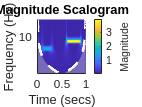

fs = 1000; t = 0:1/fs:1;
s = 2*sin(64*pi*t).*(t>=0.1 & t<0.3)+ 4*sin(128*pi*t).*(t>0.6 & t<0.9);
cwt(s,fs) %’morse’ por defecto

#### 1. Modificar las amplitudes, representar la nueva señal, calcular calcular la CWT y representar el escalograma para los 3 tipos de wavelets (Morse, Morlet y ’bump’). 

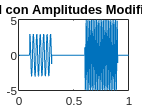

s_mod_amplitud = 3*sin(64*pi*t).*(t>=0.1 & t<0.3) + 5*sin(128*pi*t).*(t>0.6 & t<0.9);
figure;
plot(t, s_mod_amplitud);
title('Señal con Amplitudes Modificadas');

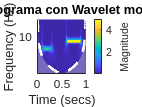

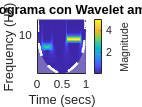

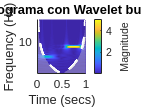


wavelets = {'morse', 'amor', 'bump'};
for i = 1:length(wavelets)
    figure;
    cwt(s_mod_amplitud, fs, wavelets{i});
    title(['Escalograma con Wavelet ', wavelets{i}]);
end

#### 2. Modificar las frecuencias y repetir los pasos anteriores. 

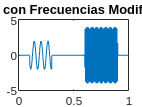

s_mod_frecuencia = 2*sin(32*pi*t).*(t>=0.1 & t<0.3) + 4*sin(256*pi*t).*(t>0.6 & t<0.9);
figure;
plot(t, s_mod_frecuencia);
title('Señal con Frecuencias Modificadas');

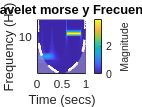

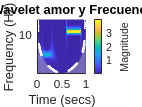

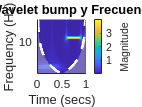


for i = 1:length(wavelets)
    figure;
    cwt(s_mod_frecuencia, fs, wavelets{i});
    title(['Escalograma con Wavelet ', wavelets{i}, ' y Frecuencias Modificadas']);
end

#### 3. Representar uno de los espectrogramas en escala lineal usando el script helperCWTTimeFreqPlot. 

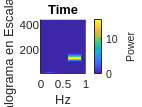

[cfs, freq] = cwt(s_mod_frecuencia, fs, 'morse');
helperCWTTimeFreqPlot(cfs, t, freq, 'surf', 'Time', 'Hz', 'Escalograma en Escala Lineal');

#### 4. Eliminar los valores del espectrograma correspondientes a la frecuencia localida entre 0.6s y 0.9s, reconstruir y representar el espectrograma de la señal reconstruida.

% Obtener la matriz de coeficientes CWT y las frecuencias
[cfs, f] = cwt(s, fs);

% Eliminar los valores del espectrograma entre 0.6s y 0.9s
% Encuentra los índices de tiempo correspondientes al intervalo de 0.6s a 0.9s
indices_tiempo = find(t >= 0.6 & t <= 0.9);
% Establece los coeficientes a cero en el rango de tiempo deseado
cfs(:, indices_tiempo) = 0;

% Reconstruir la señal a partir de la matriz de coeficientes modificada
srec = icwt(cfs, 'morse', fs);

Error using icwt>parseInputs
Frequency or period input variables must be accompanied by frequency or period range input variables.

Error in icwt (line 267)
params = parseInputs(Na,N,sigtype,datatype,varargin{:});


% Representar el espectrograma de la señal reconstruida
figure;
cwt(srec, fs);
title('Espectrograma de la Señal Reconstruida');
